Consider a Van der 

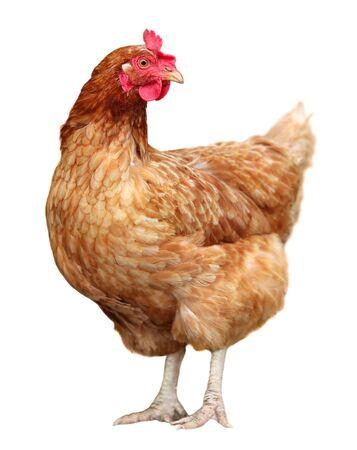

 oscillator


$$\dot{x}=y,\\
\dot{y}=-x-\epsilon(x^2-1)y.$$


calculate SSM

clear all;
epsilon=0.1;

Build model

In SSMTool, the setup of first-order autonomous systems is given as follows


$$\mathbf{B}\dot{\mathbf{z}}=\mathbf{A}\mathbf{z}+\mathbf{F}(\mathbf{z})$$


Let's have a look at 

*Exact nonlinear model reduction for a von Kármán beam: Slow-fast decomposition and spectral submanifolds*

Shobhit Jain, Paolo Tiso, George Haller

Journal of Sound and Vibration

**eq. (22) **

To understand the tensor notation for the nonlinear term in *build_model.m*

[A,B,F] = build_model(epsilon);

Dynamical system setup

DS = DynamicalSystem();
set(DS,'A',A,'B',B,'fnl',F);

Linear Modal analysis and SSM computation

[V,D,W] = DS.linear_spectral_analysis();


 The first 2 nonzero eigenvalues are given as 
   0.0500 + 0.9987i
   0.0500 - 0.9987i



S = SSM(DS);
set(S.Options,'paramStyle','graph')
masterModes = 1;                        % master mode
order = 8;                              % SSM expansion order
S.choose_E(masterModes);

sigma_out = 1
sigma_in = 1


[W0,R0] = S.compute_whisker(order);     % compute of SSM

Computing autonomous whisker at order 2
0 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 4.67E-03 MB
Computing autonomous whisker at order 3
0 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 7.25E-03 MB
Computing autonomous whisker at order 4
0 (near) inner resonance(s) detected at order 4
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 8.50E-03 MB
Computing autonomous whisker at order 5
0 (near) inner resonance(s) detected at order 5
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 9.95E-03 MB
Computing autonomous whisker at order 6
0 (near) inner resonance(s) detected at order 6
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 1.13E-02 MB
Computing autonomous whisker at order 7
0 (near) inner resonance(s) detecte

Expansion coefficients

coeffs = zeros(2,order);
for k=1:order
    if ~isempty(W0(k).coeffs); coeffs(:,k) = full(W0(k).coeffs); end
end

disp('Expansion coefficients of the SSM at various orders (ith column gives the coeffcients at order i)')

Expansion coefficients of the SSM at various orders (ith column gives the coeffcients at order i)


coeffs

coeffs =    0.7071 + 0.0000i   0.0000 + 0.0000i  -0.0001 + 0.0044i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i
   0.0354 + 0.7062i   0.0000 + 0.0000i  -0.0133 + 0.0003i   0.0000 + 0.0000i   0.0000 - 0.0002i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
